## **2.1 Probabilidade condicional, independência**

**1. Considere a variável aleatória X correspondente à face que fica para cima no lançamento de 1 dado. Usando os valores teóricos:**

(a) produza um gráfico, em Matlab, que represente a função massa de probabilidade de X;

%% Um dado tem 6 lados e, com faces de 1 a 6 e equiprováveis 
%% de calhar (P(1) = 1/6 = P(2) = 1/6 ...). Sabendo isto, podemos
%% representar a função probabilidade de X da seguinte forma:
X = 1:6;
%% Função mássica da probabilidade
p=ones(1,6)/6;
stem(X,p), xlabel("X"), ylabel("px(x)");

xlim([0 7]);

(b) num segundo gráfico da mesma figura, desenhe o gráfico da função de distribuição acumulada (use a função stairs do Matlab).

X = [1 2 3 4 5 6];
p = [1/6 1/6 1/6 1/6 1/6 1/6];
fx = cumsum(p);
y = stairs(X,fx)

y =   Stair with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6]
              YData: [0.1667 0.3333 0.5000 0.6667 0.8333 1.0000]

  Show all properties


xlim([0.8 7]);
ylim([0 1.02]);

**2. Considere uma caixa contendo 90 notas de 5 Euros, 9 notas de 50 e 1 de 100.**

(a) Descreva o espaço de amostragem da experiência aleatória, retirar uma nota da caixa, e as probabilidades dos acontecimentos elementares.

%% Temos 100 acontecimentos elementares, todos equiprováveis que 
%% correspondem a calhar cada uma das notas {nota1, nota2, ..., nota100}
%% , cuja probabilidade é 1/100

   (b) Considere agora a variável aleatória X como sendo o valor de uma nota retirada à sorte da caixa acima descrita. Descreva o espaço de amostragem e a função massa de probabilidade de X.

%% p(5) = 0.900
%% p(50) = 0.090
%% p(100) = 0.010

(c) Determine a função distribuição acumulada de X e efectue a sua representação gráfica em Matlab.

x = [5 50 100];
px = [0.90 0.09 0.01];
fx = cumsum(px)

stairs([0 x 110],[0 fx 1])
grid on
ylim([0 1.1])
xlim([0 110])
   

**3. Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observados nos 4 lançamentos.**

(a) Estime por simulação a função massa de probabilidade pX (x) da variável aleatória X.

prob = 0.5;
N= 1e5;
probArray = zeros(5,1);
experiencias = rand(4,N) < prob;
for index = 1:1:5
    for i = 1:N
        column = experiencias(:,i);
        probArray(index) = probArray(index) + (sum(column) == (index-1));
    end
end

probArray = probArray / N

probArray =     0.0619
    0.2501
    0.3759
    0.2495
    0.0626


bar(probArray)

fprintf("f(0)= %.4f\n", probArray(1))

f(0)= 0.0619


fprintf("f(1)= %.4f\n", probArray(2))

f(1)= 0.2501


fprintf("f(2)= %.4f\n", probArray(3))

f(2)= 0.3759


fprintf("f(3)= %.4f\n", probArray(4))

f(3)= 0.2495


fprintf("f(4)= %.4f\n", probArray(5))

f(4)= 0.0626


(b) Estime o valor esperado, a variância e o desvio padrão de X com base em pX (x).

X = [0 1 2 3 4];

avg = X*probArray

avg = 2.0007

%% média de ((array de acontecimentos X - média (array de acontecimentos X)) ao quadrado)
sigma = ((X - avg).^2)

sigma =     4.0028    1.0014    0.0000    0.9986    3.9972


%% 
var = sigma*probArray

var = 0.9977

%% sqrt da Variância
desvioP = sqrt(var)

desvioP = 0.9988

(c) Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teórica da respectiva função de probabilidade.

%% O tipo de distribuição é Binomial, com p=0.5 e n=4

(d) Calcule os valores teóricos da função massa de probabilidade de X e compare-os com os valores estimados por simulação obtidos em (a)

pArrayT = zeros(5,1);
for i = 0:1:4
    pArrayT(i+1) = nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
    fprintf("p(%d)= %.4f\n",i,pArrayT(i+1));
end

p(0)= 0.0625
p(1)= 0.2500
p(2)= 0.3750
p(3)= 0.2500
p(4)= 0.0625


(e) Calcule os valores teóricos de E[x] e de Var(X) e compare-os com os valores obtidos em (b).

X = [0 1 2 3 4];
avg = X*pArrayT;
var = ((X - avg).^2)*pArrayT;
desvioP = sqrt(var);

fprintf("Average= %.4f\n Variancia= %.4f\n Desvio Padrão= %.4f",avg,var,desvioP);

Average= 2.0000
 Variancia= 1.0000
 Desvio Padrão= 1.0000

(f) Com base nos valores teóricos da função massa de probabilidade desta distribuição, calcule:

i. a probabilidade de obter pelo menos 2 coroas;

ii. a probabilidade de obter até 1 coroa;

iii. a probabilidade de obter entre 1 e 3 coroas, inclusive.

pI = 0;
pII = 0;
pIII = 0;
for i=2:1:4
    pI = pI + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

for i= [0 1]
    pII = pII + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

for i = [1 2 3]
    pIII = pIII + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

fprintf("Probabilidade de i) p= %.4f\n", pI)

Probabilidade de i) p= 0.6875


fprintf("Probabilidade de ii) p= %.4f\n", pII)

Probabilidade de ii) p= 0.3125


fprintf("Probabilidade de iii) p= %.4f", pIII)

Probabilidade de iii) p= 0.8750

**4. Sabendo que um processo de fabrico produz 30% de peças defeituosas e considerando a variável aleatória X, representativa do número de peças defeituosas numa amostra de 5 peças tomadas aleatoriamente, obtenha:**

(a) Por simulação:

i. estimativa para a função massa de probabilidade de X;

p = 0.30;
N = 1e5;

successArray = zeros(6,1);
experiencias = rand(5,1,N) < p;
for i= 1:N
    column = experiencias(:,i);
    pecasDef = sum(column);
    successArray(1) = successArray(1) + (pecasDef == 0);
    successArray(2) = successArray(2) + (pecasDef == 1);
    successArray(3) = successArray(3) + (pecasDef == 2);
    successArray(4) = successArray(4) + (pecasDef == 3);
    successArray(5) = successArray(5) + (pecasDef == 4);
    successArray(6) = successArray(6) + (pecasDef == 5);
end
probArray = successArray/N

probArray =     0.1701
    0.3603
    0.3079
    0.1312
    0.0281
    0.0024


for i=1:6
    fprintf("Probabilidade de %d pecas defeituosas %.4f\n",i-1, probArray(i));
end    

Probabilidade de 0 pecas defeituosas 0.1701
Probabilidade de 1 pecas defeituosas 0.3603
Probabilidade de 2 pecas defeituosas 0.3079
Probabilidade de 3 pecas defeituosas 0.1312
Probabilidade de 4 pecas defeituosas 0.0281
Probabilidade de 5 pecas defeituosas 0.0024


ii. o gráfico representativo da função distribuição acumulada de probabilidades de X;

X = [0 1 2 3 4 5];
fx = cumsum(probArray);
stairs(X,fx);
xlim([-0.2 5.2])
ylim([0 1.1])

iii. estimativa para probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas.

%% Neste caso, contabilizamos 0, 1 ou 2 peças defeituosas
prob = probArray(1) + probArray(2) + probArray(3);
fprintf("Probabilidade de no máximo 2 peças terem defeito= %.4f", prob);

Probabilidade de no máximo 2 peças terem defeito= 0.8383

(b) Analiticamente:

i. a função distribuição acumulada de X;

probAn = zeros(6,1);
p = 0.30

p = 0.3000

n = 5;
for k=0:4
    probAn(k+1) = nchoosek(n,k)*p^k*(1-p)^(n-k);
end
X = [0 1 2 3 4 5];
fx= cumsum(probAn);
stairs(X,fx);
xlim([-0.2 5.2]);
ylim([0 1.1])

ii. a probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas.

%% Esta probabilidade corresponde à soma das probabilidades de haver
%% 0, 1 ou 2 peças defeituosas, ou seja:
prob = probAn(1) + probAn(2) + probAn(3);
fprintf("Probabilidade teórica de no máx. 2 peças defeituosas: %.4f",prob);

Probabilidade teórica de no máx. 2 peças defeituosas: 0.8369

**5. Suponha que o(s) motor(es) de um avião pode(m) falhar com probabilidade p e que as falhas são independentes entre motores. Suponha ainda que o avião se despenha se mais de metade dos motores falharem. Nestas condições, prefere voar num avião com 2 ou 4 motores? Utilize a distribuição que considerar mais adequada. **

**Tem pelo menos 2 alternativas: **

(1) obter expressões para a probabilidade de cada tipo de avião se despenhar em função de p e usar o quociente entre ambas para responder à questão 

(2) efectuar os cálculos para um conjunto de valores concretos de p (ex: p= logspace(-3,log10(1/2),100)) e usar um gráfico mostrando simultaneamente as probabilidades de cada tipo de avião se despenhar.

%% Para resolver este problema, basta obtermos as expressões de probabilidade
%% de despenhamento para o caso do avião com 2 motores e o caso do avião com 4 motores
%% Para o avaio com 2 motores se despenhar, ambos os motores têm que deixar de funcionar
%% p2 = nchoosek(2,2)*p^2*(1-p)^(2-2) = p^2
%% Para o aviao com 4 motores se despenhar, 3 dos seus 4 motores têm que deixar de funcionar
%% p4 = nchoosek(4,3)*p^3*(1-p)^(4-3) = 4p^3 - 3p^4
%% Relação entre os 2 casos = (4p^3 - 3p^4) / p^2 = 4p-3p^2 = p(4 - 3p)
%%

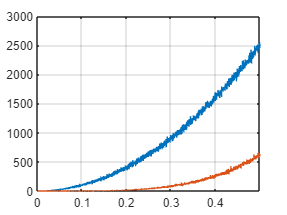

%% p = logspace de probabilidades de 1 motor falhar
p = logspace(-3,log10(1/2),10000);
N = length(p);
crashCounter = zeros(1,N);
for m = [2 4]
    for i = 1:N
        experiencias = rand(m,N) < p(i);
        crashCounter(i) = sum(sum(experiencias) == m);
    end
    plot(p, crashCounter);
    hold on
    grid on
end
hold off

**6. A distribuição de Poisson é uma forma limite da distribuição binomial (quando n → ∞ , p → 0 e np permanece constante) e portanto pode ser usada para aproximar e simplificar os cálculos envolvidos com a binomial em situações em que as condições anteriores se verifiquem. Num processo industrial de fabrico de chips, alguns aparecem defeituosos tornando-os inapropriados para comercialização. É sabido que em média por cada 1000 chips há um defeituoso.**

Pr (𝑋 = 𝑘) = 𝜆𝑘 * 𝑒^−𝜆 / 𝑘! , k = 1,2,3, ...

(a) Usando a distribuição binomial, determine a probabilidade de numa amostra de 8000 chips aparecerem 7 defeituosos.

pDef = 1/1000;
n=8000;
k=7;

P_Binomial = nchoosek(n,k) * pDef^k * (1-pDef)^(n-k)

P_Binomial = 0.1396

(b) Determine a mesma probabilidade usando a aproximação de Poisson e compare o resultado com o da alínea anterior.

ValorEsp = 8000/1000; %% pois em cada 1000 há 1 def., logo é de esperar que em cada 8000 haja 8 def.
lambda = ValorEsp;
P_Poisson = lambda^k / factorial(k) *exp(-lambda)

P_Poisson = 0.1396

**7. Suponha que o número de mensagens que chega a um servidor de email segue uma lei de Poisson com média de 15 (mensagens por segundo). Calcule a probabilidade de num intervalo de um segundo:**

(a) o servidor não receber nenhuma mensagem

ValorEsp = 15;
lambda = ValorEsp;
k = 0;
P_Poisson = lambda^k / factorial(k) * exp(-lambda);

P_Poisson = 3.0590e-07

fprintf("A probabilidade de o servidor não receber nenhuma mensagem após 1s é= %.10f",P_Poisson);

A probabilidade de o servidor não receber nenhuma mensagem após 1s é= 0.0000003059

(b) o servidor receber mais de 10 mensagens.

%% Neste caso, teriamos que considerar valores de k = 10,11,12,13,14,... +inf.
%% Temos que ir pelo cálculo da probabilidade do complementar, pois
%% só podemos aplicar a distribuição de Poisson a valores discretos.
%% Portanto queremos descobrir P(~B), onde 
%% B: o servidor receber 10 ou menos mensagens
PnotB = 0;
for k = 0:10
    PnotB = PnotB + lambda^k / factorial(k) * exp(-lambda);
end
PB = 1 - PnotB;
fprintf("A probabilidade de o servidor receber mais do que 10 mensagens é= %.6f", PB);

A probabilidade de o servidor receber mais do que 10 mensagens é= 0.881536

**8. Assumindo que o número de erros tipográficos numa página de um livro tem uma distribuição de Poisson com λ = 0.02, calcule a probabilidade de que exista no máximo 1 erro num livro de 100 páginas. Considere que o número de erros em cada página é independente do número de erros nas outras páginas.**

lambda1 = 0.02;
lambda100 = 0.02 * 100; 
%% Para cada página existe uma prob de erro de 0.02, então nas 100 páginas
%% a prob de erro é de 0.02*100 (pois o nº erros numa página é independente
%% do nº de erros nas outras páginas)
k = 0;
P0 = lambda^k / factorial(k) * exp(-lambda);
k = 1;
P1 = lambda^k / factorial(k) * exp(-lambda);
Ptotal = P0 + P1;
fprintf("A probabilidade de existir no máximo 1 erro num livro de 100 páginas é= %.10f", Ptotal);

A probabilidade de existir no máximo 1 erro num livro de 100 páginas é= 0.0000048944

**9. Considerando a variável aleatória X, representativa das classificações dos alunos de um determinado curso, contínua e com distribuição normal (média 14 e desvio padrão 2), obtenha através de simulação uma estimativa para as probabilidades de:**

(a) um aluno do curso ter uma classificação entre 12 e 16

ro = 2;